% uppgift 1-3
syms z
X1 = 2*(z^-1)+4*(z^-2)+5*(z^-3)+3*(z^-4)+2*(z^-5);
iztrans(X1)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$

%ans: 2*Delta(n - 1) + 4*Delta(n - 2) + 5*Delta(n - 3) + 3*Delta(n - 4) + 2*Delta(n - 5)
% Detta betyder att funktionen X1 är antingen 0, 2, 4, 5, 3, 2 då
% n = 0,1,2,3,4,5

% upgift 4-6
syms z
X1prim = (2*(z^4)+4*(z^3)+5*(z^2)+3*(z)+2)*(z^-5);
iztrans(X1prim)

$$ans = 2\,\delta_{n-1,0}+4\,\delta_{n-2,0}+5\,\delta_{n-3,0}+3\,\delta_{n-4,0}+2\,\delta_{n-5,0}$$

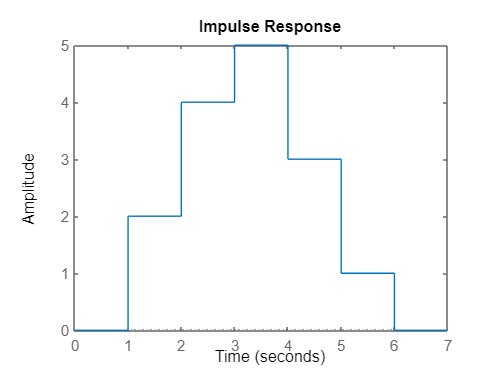

num = [0 2 4 5 3 1];
den = [1 0 0 0 0 0];
dimpulse(num,den, 8)

% uppgift 7-9
syms z
X2 = ((z^2)-(z^1))/(2*(z^2)-(z^1)-1)

$$X2 = \frac{z-z^{2}}{-2\,z^{2}+z+1}$$

iztrans(X2)

$$ans = \frac{{\left(-\frac{1}{2}\right)}^{n}}{2}$$

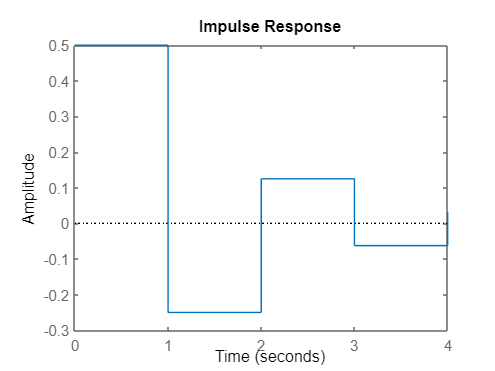

num = [1 -1 0];
den = [2 -1 -1];
dimpulse(num,den,5);

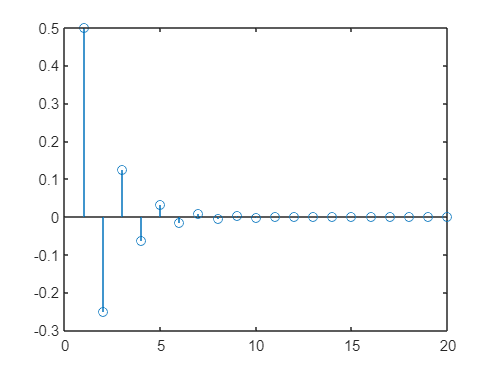

stem(dimpulse(num,den, 20));

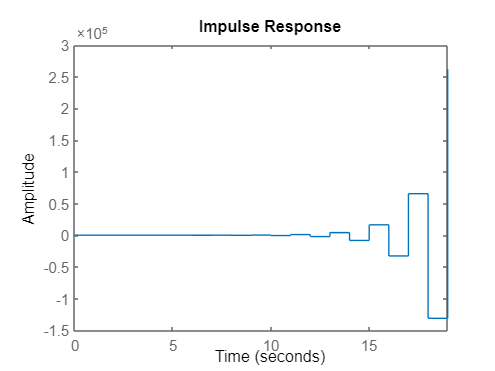

% 3.6 uppgift 10-11
syms z
X1 = 1/((z^1)+2);
dimpulse([0 1],[1 2],20);

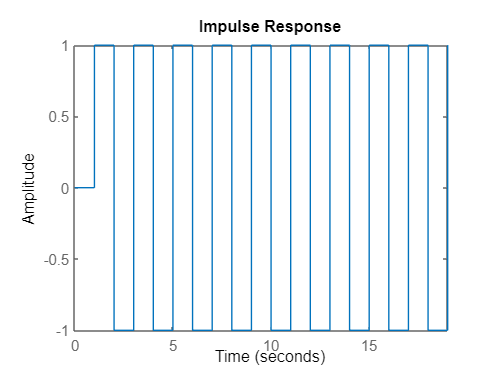



X2 = 1/((z^1)+1);
dimpulse([0 1],[1 1],20);

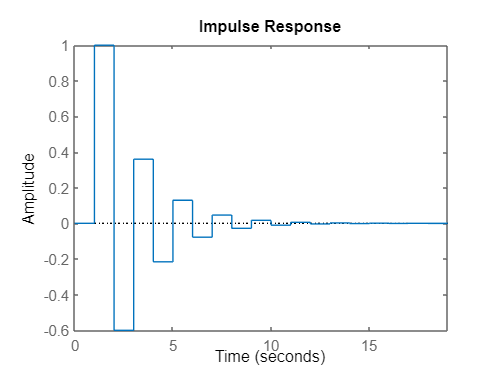


X3 = 1/((z^1)+0.6);
dimpulse([0 1],[1 0.6],20);

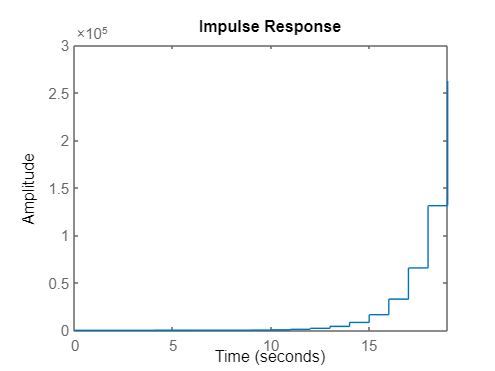


X4 = 1/((z^1)-2);
dimpulse([0 1],[1 -2],20);

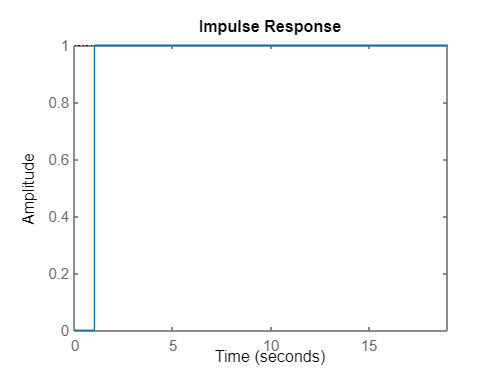


X5 = 1/(z-1);
dimpulse([0 1], [1 -1],20);

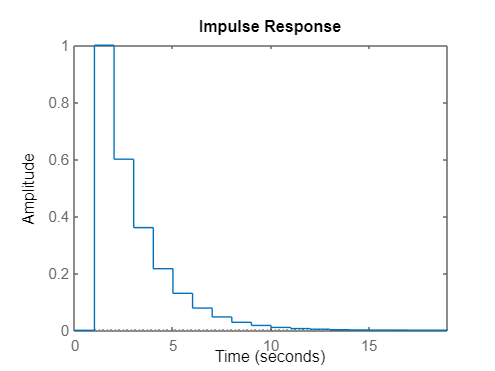


X6 = 1/(z-0.6);
dimpulse([0 1], [1 -0.6], 20);

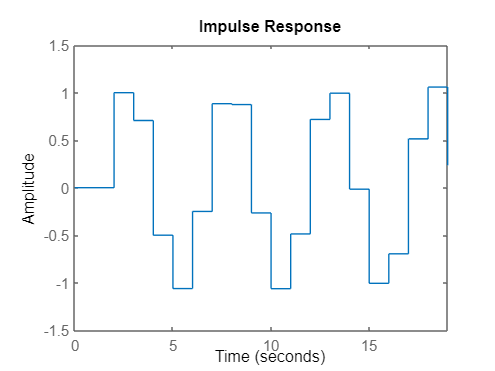


X7 = 1/(sqrt(2)*(z^2)-2*(z^1)+sqrt(2));
dimpulse([0 0 1], [1 -((1/sqrt(2)) + 1i*(1/sqrt(2)) - 1i*(1/sqrt(2))) 1], 20);

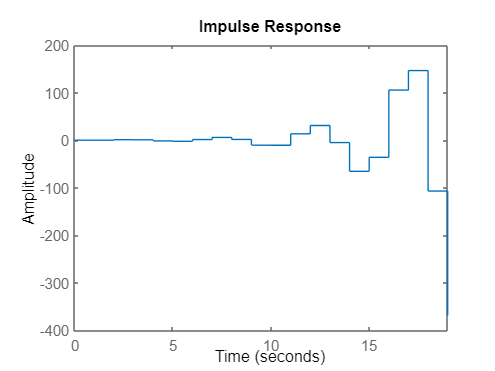


dimpulse([0 0 1], [1 -((1/sqrt(2)) + 1i*(1/sqrt(2)) - 1i*(1/sqrt(2))) 2], 20);

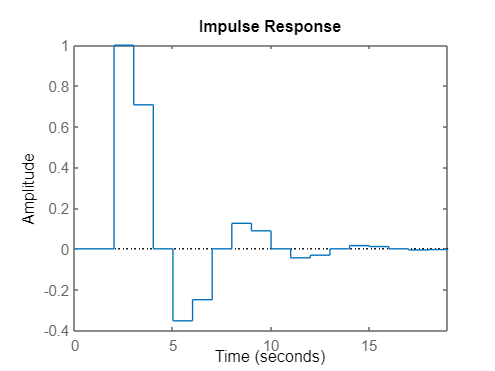

dimpulse([0 0 1], [1 -((1/sqrt(2)) + 1i*(1/sqrt(2)) - 1i*(1/sqrt(2))) 0.5], 20);

% uppgift 12-13
syms z
X = 1/((z^2)+1.5*(z^1)+0.5);
iztrans(X)

$$ans = 2\,{\left(-1\right)}^{n}-4\,{\left(-\frac{1}{2}\right)}^{n}+2\,\delta_{n,0}$$

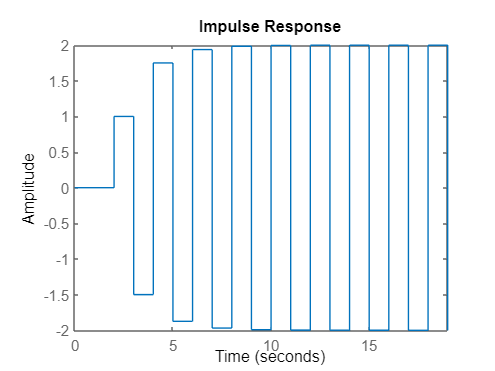

dimpulse([0 0 1],[1 1.5 0.5],20);

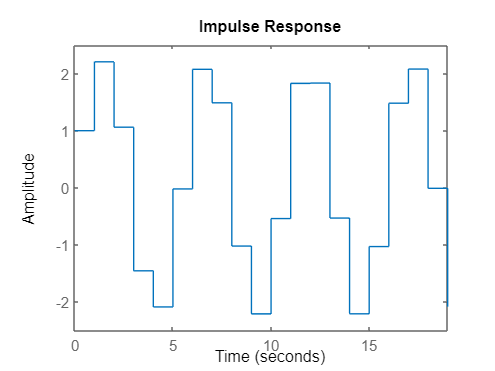

dimpulse([1 1.5 0.5], [1 -((1/sqrt(2)) + 1i*(1/sqrt(2)) - 1i*(1/sqrt(2))) 1], 20);

% uppgift 14-19
[x,fs]=audioread("mooncradle.wav");
Hz2Remove = 200;
H = (z^2) - z*(2* cos(2*Hz2Remove*pi/fs)) +c

$$H = z^{2}-\frac{4496287987864779\,z}{2251799813685248}+1$$

numHk = ([1 -(2* cos(2*Hz2Remove*pi/fs)) 1]);
denHk = ([1 0 0]);
h = dimpulse(numHk, denHk);
y = conv(x, h);
soundsc(y,fs);